% Example of a 2R planar robot
num_joints = 2;

$$a = \left(\begin{array}{ccccc} a_{1} & a_{2} & a_{3} & a_{4} & a_{5} \end{array}\right)$$

l = sym('l', [1 num_joints])

$$l = \left(\begin{array}{cc} l_{1} & l_{2} \end{array}\right)$$

q = sym('q', [1 num_joints])

$$q = \left(\begin{array}{cc} q_{1} & q_{2} \end{array}\right)$$

q_dot = sym('q_dot_%d', [1 num_joints])

$$q\_dot = \left(\begin{array}{cc} {\dot{q}}_{1} & {\dot{q}}_{2} \end{array}\right)$$

q_ddot = sym('q_ddot_%d', [1 num_joints])

$$q\_ddot = \left(\begin{array}{cc} {\ddot{q}}_{1} & {\ddot{q}}_{2} \end{array}\right)$$


% Direct Kinematics
f = [l(1)*cos(q(1)) + l(2)*cos(q(1)+q(2));
     l(1)*sin(q(1)) + l(2)*sin(q(1)+q(2));
     0]

$$f = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

% Diff Kinematics
J = jacobian(f, q)

$$J = \left(\begin{array}{cc} -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0 \end{array}\right)$$

J_dot = time_diff(J, q.', q_dot.')

$$J\_dot = \left(\begin{array}{cc} -l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)-l_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right) & -l_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ -l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)-l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$M = \left(\begin{array}{cc} a_{1}+2\,a_{2}\,\cos\left(q_{2}\right) & a_{3}+a_{2}\,\cos\left(q_{2}\right)\\ a_{3}+a_{2}\,\cos\left(q_{2}\right) & a_{3} \end{array}\right)$$

$$c = \left(\begin{array}{c} -a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ a_{2}\,{{\dot{q}}_{1}}^{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

$$g = \left(\begin{array}{c} a_{5}\,\cos\left(q_{1}+q_{2}\right)+a_{4}\,\cos\left(q_{1}\right)\\ a_{5}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

% Desired joint trajectory
syms t
q_d = [pi/2 + 3*sin(pi*t/2);
       1 - cos(2*pi*t)]

$$q\_d = \left(\begin{array}{c} \frac{\pi }{2}+3\,\sin\left(\frac{\pi \,t}{2}\right)\\ 1-\cos\left(2\,\pi \,t\right) \end{array}\right)$$

q_d_dot = diff(q_d)

$$q\_d\_dot = \left(\begin{array}{c} \frac{3\,\pi \,\cos\left(\frac{\pi \,t}{2}\right)}{2}\\ 2\,\pi \,\sin\left(2\,\pi \,t\right) \end{array}\right)$$

q_d_ddot = diff(q_d_dot)

$$q\_d\_ddot = \left(\begin{array}{c} -\frac{3\,\pi^{2}\,\sin\left(\frac{\pi \,t}{2}\right)}{4}\\ 4\,\pi^{2}\,\cos\left(2\,\pi \,t\right) \end{array}\right)$$

ts = 0:0.05:1;
q_d_eval = eval(subs(q_d, ts));
q_d_dot_eval = eval(subs(q_d_dot, ts));
q_d_ddot_eval = eval(subs(q_d_ddot, ts));
f_d_eval = [];
v_d_eval = [];
a_d_eval = [];
% v_accum = [0; 0; 0];
vars = [l(1), l(2), q(1), q(2), q_dot(1), q_dot(2)];
for i=1:size(q_d_eval, 2)
   vals = [1, 1, q_d_eval(1, i), q_d_eval(2, i), q_d_dot_eval(1, i), q_d_dot_eval(2, i)];
   f_d_eval = [f_d_eval, eval(subs(f, vars, vals))];
   J_eval = eval(subs(J, vars, vals));
   v_d_eval = [v_d_eval, J_eval * q_d_dot_eval(:, i)];
   J_dot_eval = eval(subs(J, vars, vals));
   a_d_eval = [a_d_eval, J_eval * q_d_ddot_eval(:, i) + J_dot_eval * q_d_dot_eval(:, i)];
   % v_accum = [v_accum, v_accum(:, end) + v_d_eval(:, end)];
end
% v_accum = v_accum(:, 2:end);

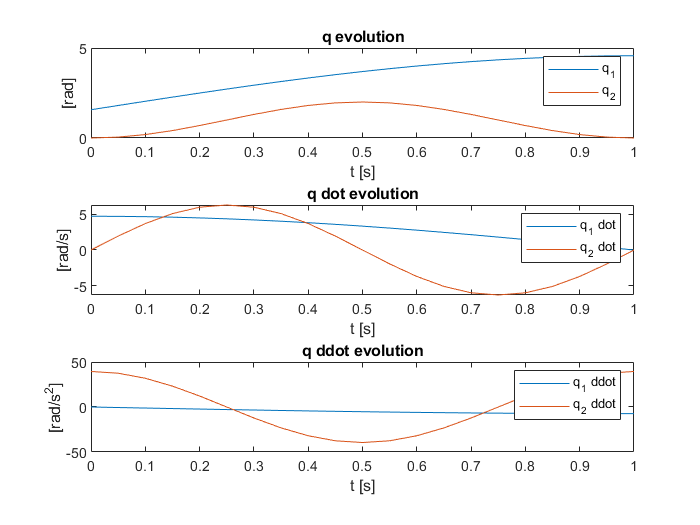

f = figure;
subplot(3,1,1);
plot(ts,q_d_eval(1, :), 'DisplayName','q_1')
hold on;
plot(ts,q_d_eval(2, :), 'DisplayName','q_2')
xlabel('t [s]');
ylabel('[rad]');
legend;
title('q evolution')

subplot(3,1,2); 
plot(ts,q_d_dot_eval(1, :), 'DisplayName','q_1 dot')
hold on;
plot(ts,q_d_dot_eval(2, :), 'DisplayName','q_2 dot')
xlabel('t [s]');
ylabel('[rad/s]');
legend;
title('q dot evolution')

subplot(3,1,3); 
plot(ts,q_d_ddot_eval(1, :), 'DisplayName','q_1 ddot')
hold on;
plot(ts,q_d_ddot_eval(2, :), 'DisplayName','q_2 ddot')
xlabel('t [s]');
ylabel('[rad/s^2]');
legend;
title('q ddot evolution')

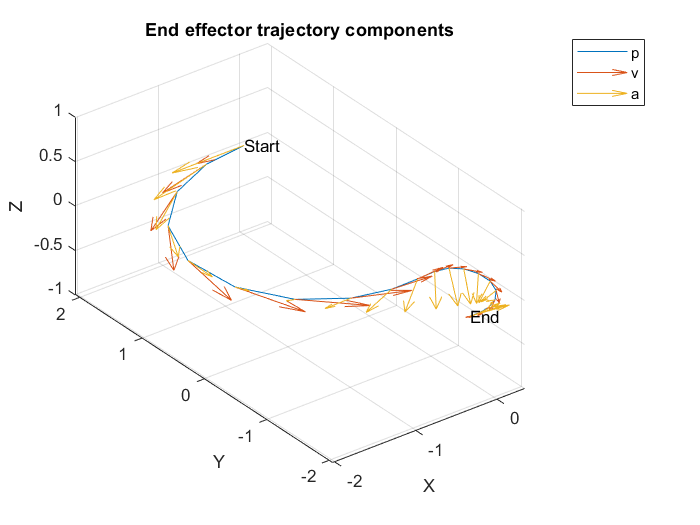

f = figure;
plot3(f_d_eval(1, :), f_d_eval(2, :), f_d_eval(3, :), 'DisplayName','p')
hold on;
quiver3(f_d_eval(1, :), f_d_eval(2, :), f_d_eval(3, :), ... 
    v_d_eval(1, :), v_d_eval(2, :), v_d_eval(3, :), 'DisplayName','v')
hold on;
quiver3(f_d_eval(1, :), f_d_eval(2, :), f_d_eval(3, :), ... 
   a_d_eval(1, :), a_d_eval(2, :), a_d_eval(3, :), 'DisplayName','a')
hold on;
text(f_d_eval(1, 1), f_d_eval(2, 1), f_d_eval(3, 1), "Start")
hold on;
text(f_d_eval(1, end), f_d_eval(2, end), f_d_eval(3, end), "End")
title('End effector trajectory components');
axis equal, grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
legend;